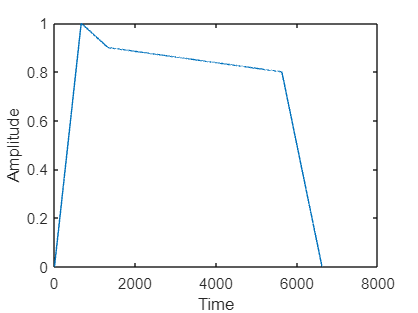

load bach_fugue.mat

theVoices.noteNumbers;
theVoices.startPulses;
theVoices.durations;

bpm = 60;
beats_per_second = bpm/60;
seconds_per_beat = 1/beats_per_second;
seconds_per_pulse = seconds_per_beat/4;
fs = 22050;

tt = [0:1/fs:250*seconds_per_pulse];
xx = zeros(size(tt));

num_voices = length(theVoices);

for k = 1:num_voices % loop over voices
    for idx = 1:length(theVoices(k).startPulses)
        tone = key2note_env(1,theVoices(k).noteNumbers(idx),theVoices(k).durations(idx)*seconds_per_pulse,fs); % note for voice k, start pulse i
        start_indx = ceil((theVoices(k).startPulses(idx)-1)*seconds_per_pulse*fs)+1; % start index of note
        stop_indx = start_indx + length(tone)-1; % stop index of note
        xx(start_indx:stop_indx) = xx(start_indx:stop_indx) + tone;
    end
end

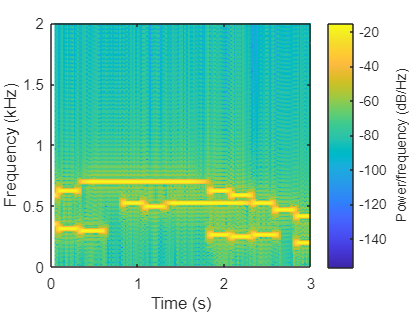


bach_env = xx;
spectrogram(bach_env(500000:580000),2048,1600,8192,fs,'yaxis')
xlim([0,3])
ylim([0,2])

soundsc( bach_env, fs )

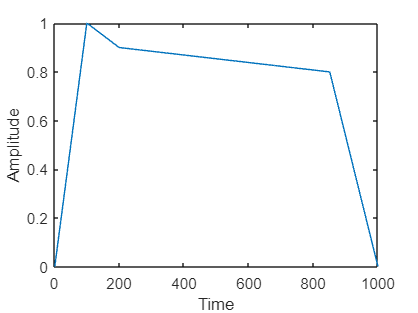

E =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


E = getADSR(1000)

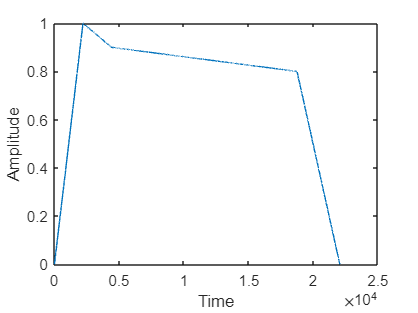

env =          0    0.0005    0.0009    0.0013    0.0016    0.0018    0.0020    0.0020    0.0020    0.0017    0.0014    0.0010    0.0004   -0.0003   -0.0012   -0.0021   -0.0031   -0.0041   -0.0052   -0.0063   -0.0073   -0.0083   -0.0093   -0.0101   -0.0108   -0.0113   -0.0117   -0.0119   -0.0118   -0.0116   -0.0111   -0.0103   -0.0094   -0.0081   -0.0067   -0.0051   -0.0032   -0.0012    0.0009    0.0031    0.0054    0.0077    0.0100    0.0123    0.0144    0.0164    0.0182    0.0197    0.0210    0.0220


env = key2note_env(1,49,1,fs)

not_env = key2note(1,49,1,fs)

not_env =     1.0000    0.9922    0.9687    0.9301    0.8769    0.8099    0.7301    0.6390    0.5378    0.4281    0.3117    0.1905    0.0662   -0.0591   -0.1835   -0.3049   -0.4216   -0.5317   -0.6335   -0.7253   -0.8057   -0.8734   -0.9275   -0.9669   -0.9912   -1.0000   -0.9930   -0.9705   -0.9327   -0.8803   -0.8140   -0.7350   -0.6444   -0.5437   -0.4345   -0.3185   -0.1974   -0.0733    0.0520    0.1765    0.2982    0.4152    0.5257    0.6279    0.7203    0.8014    0.8699    0.9248    0.9651    0.9903



%soundsc(env,fs)
%soundsc(not_env,fs)

for k = 1:num_voices % loop over voices
    for idx = 1:length(theVoices(k).startPulses)
        tone = key2note_fancy(1,theVoices(k).noteNumbers(idx),theVoices(k).durations(idx)*seconds_per_pulse,fs); % note for voice k, start pulse i
        start_indx = ceil((theVoices(k).startPulses(idx)-1)*seconds_per_pulse*fs)+1; % start index of note
        stop_indx = start_indx + length(tone)-1; % stop index of note
        xx(start_indx:stop_indx) = xx(start_indx:stop_indx) + tone;
    end
end

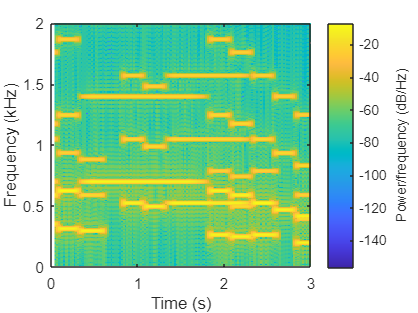


bach_fancy = xx;
spectrogram(bach_fancy(500000:580000),2048,1600,8192,fs,'yaxis')
xlim([0,3])
ylim([0,2])

soundsc( bach_fancy, fs )